clear all
close all

# Trajectory Generation

Generate **minimum time** trajectory for a ground robot. The vehicle's dynamics are governed by


$$\dot{p}_x = V \cos(\psi) \\
\dot{p}_y = V \sin(\psi) \\
\dot{\psi} = \omega $$


Initial and final conditions are 

$p_{init} = [0 , 0]^\top$, $\psi_{init} = \pi/3$,

$p_{fin} = [10 , 10]^\top$, $\psi_{fin} = \pi/3$.

The vehicle must obey to speed and angular rate constraints, i.e.,

$0 \leq V \leq 5 \, \qquad |\omega| \leq 1
$.

Finally, the vehicle must avoid an obstacle positioned at


$$p_{obs} = [5 , 5]^\top$$


by maintaining a minimum separation of $d_{sep} = 0.5$ from $p_{obs}$.

## Load Parameters

CONSTANTS.N = 25; % Order of approximation
N = CONSTANTS.N;
CONSTANTS.pinit = [0;0];
CONSTANTS.pfin = [10;10];
CONSTANTS.headin = pi/3;
CONSTANTS.headout = pi/3;
CONSTANTS.pobs = [5 5]';
CONSTANTS.sep = 0.5;
CONSTANTS.vmax = 5;
CONSTANTS.omegamax = 1;

## Initial guess

x1 = linspace(CONSTANTS.pinit(1),CONSTANTS.pfin(1),N+1)';
x2 = linspace(CONSTANTS.pinit(2),CONSTANTS.pfin(2),N+1)';
T = 10;
x0 = [x1;x2;T];

## Linear Constraints and UL Bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

## Optimize

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',3000000);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.269867 seconds.


## Plot

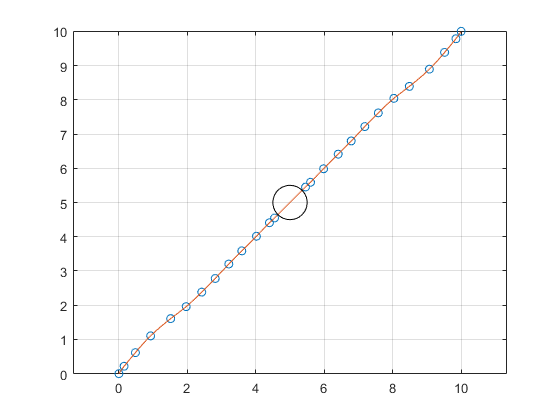

N = CONSTANTS.N;

%% Grab LGL Trajectories

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
T = x(end);

[tnodes,w,Diff] = LGL_PS(CONSTANTS.N,T);

u1 = x1'*Diff;
u2 = x2'*Diff;

unorm = sqrt((u1).^2+(u2).^2);


%% Plot
t = 0:0.01:T;
figure
plot(x1,x2,'o'); hold on
plot(LagrangePoly(x1,tnodes,t),LagrangePoly(x2,tnodes,t));
grid on
pos = [CONSTANTS.pobs(1)-CONSTANTS.sep CONSTANTS.pobs(2)-CONSTANTS.sep 2*CONSTANTS.sep 2*CONSTANTS.sep]; 
%pos = [1 2 4 4]; 
rectangle('Position',pos,'Curvature',[1 1])
axis equal

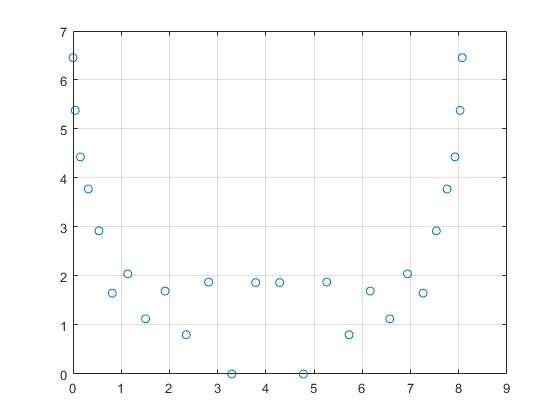



figure
plot(tnodes,unorm,'o'); hold on
grid on

## Cost Function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 

T = x(end);

J = T;
end

## Nonlinear Constraints

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
T = x(end);

[~,~,Diff] = LGL_PS(N,T);
 
u1 = x1'*Diff;
u2 = x2'*Diff;

unorm = sqrt((u1).^2+(u2).^2);

angle = atan2(u2,u1);

angrate = angle*Diff;

dist2obs = sqrt((x1-CONSTANTS.pobs(1)).^2 + (x2-CONSTANTS.pobs(2)).^2);


c=[unorm'-CONSTANTS.vmax;angrate'-CONSTANTS.omegamax;-angrate'-CONSTANTS.omegamax;angle'-pi/2;-angle'-pi/2; -dist2obs + CONSTANTS.sep];
ceq=[x1(1)-CONSTANTS.pinit(1);x2(1)-CONSTANTS.pinit(2);x1(end)-CONSTANTS.pfin(1);x2(end)-CONSTANTS.pfin(2);angle(1)-CONSTANTS.headin;angle(end)-CONSTANTS.headout;];

end